# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 800; % # sample points
A = 21; % Magnitude/Amplitude of droplet
c1 = 0.001264379882813;
c2 = 0.016807519531250;
tfinal = 10^5; % final time >> 1
xMax = 80; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
xI0 = 5;
xB0 = 10;
xC0 = 12;
xO0 = 15;

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

Inside

figure;

hold on

plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

title('2-D profile of droplet');
% legend('Initial location','Optimised location','Target shape','Location','northwest');
[tSpanI,D1,D2,X,H0I,myObjective_Possition,conds_SolI,...
    fvalI,exitflagI,outputI,historyI,h_SolI,H_SolI,costI1,HI1]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xI0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          117.335         
     1            2          117.335         initial simplex
     2            4           109.83         expand
     3            6          89.7377         expand
     4            8          45.4737         expand
     5           10          22.2335         reflect
     6           12          22.2335         contract inside
     7           14          16.4523         contract inside
     8           16          16.4244         contract inside
     9           18          16.4243         contract inside
    10           21          16.4243         shrink
    11           23          16.4243         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



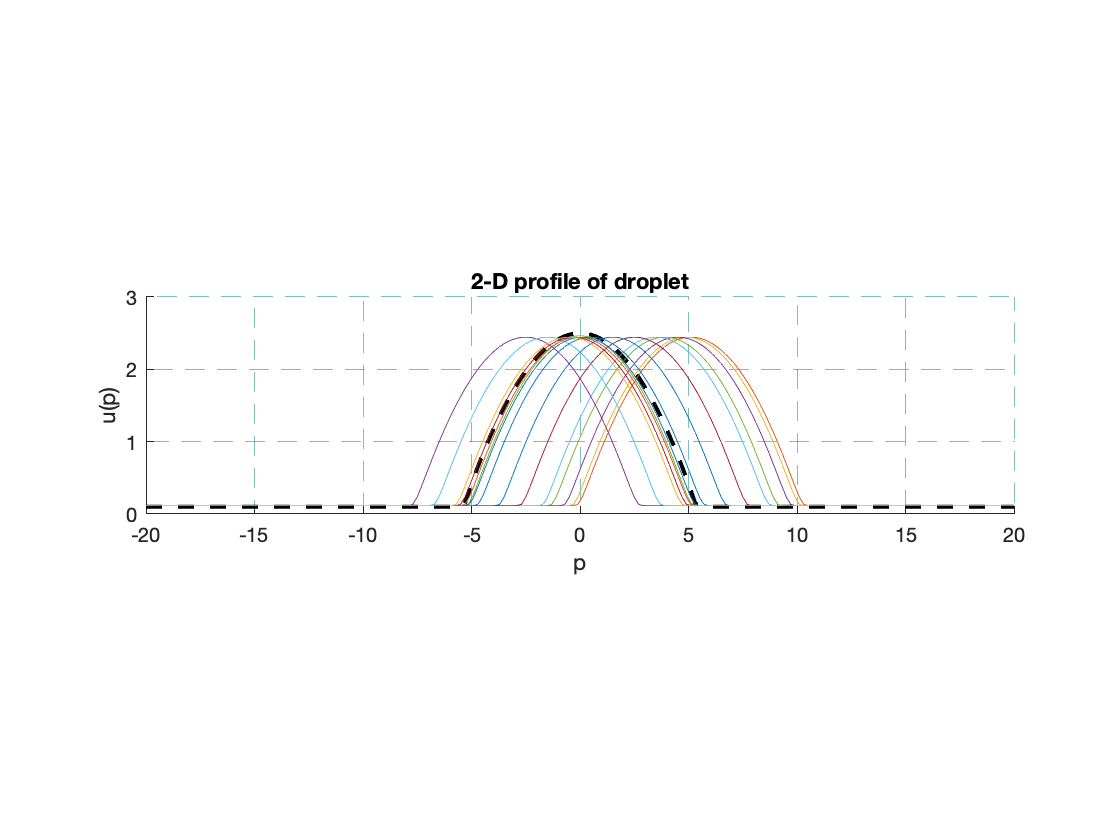

hold off


nI = size(historyI);
nI1 = nI(1);
dataHI = abs(historyI(1:8,1))';
dataHIi = abs(historyI(:,1))';
lineHI = 1:1:8;
lineHIi = 1:1:nI1;
[pI,SI,muI] = polyfit(lineHI,dataHI,1);
[pHI,deltaI] = polyval(pI,lineHI,SI,muI);

xIi = linspace(1, nI1, 100); 
yIi = interp1(lineHIi, dataHIi, xIi, 'spline', 'extrap');


Boarder

figure;

hold on

plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

title('2-D profile of droplet');
% legend('Initial location','Optimised location','Target shape','Location','northwest');

[tSpanB,D1,D2,X,H0B,myObjective_Possition,conds_SolB,...
    fvalB,exitflagB,outputB,historyB,h_SolB,H_SolB,costB1,HB1]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xB0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            173.8         
     1            2            173.8         initial simplex
     2            4          169.009         expand
     3            6          151.723         expand
     4            8          79.3554         expand
     5           10          33.9276         reflect
     6           12          33.9276         contract inside
     7           14          16.4523         contract inside
     8           16          16.4523         contract inside
     9           18          16.4244         contract inside
    10           20          16.4243         contract inside
    11           23          16.4243         shrink
    12           25          16.4243         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



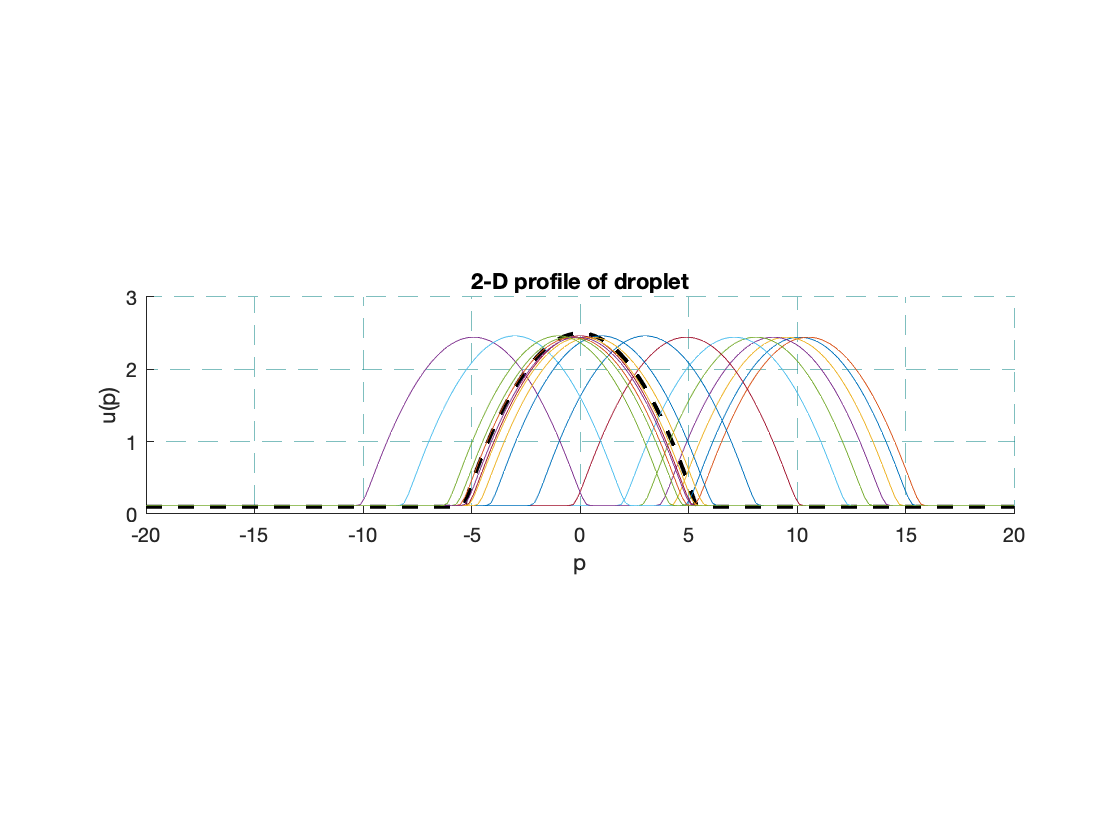


hold off


nB = size(historyB);
nB1 = nB(1);
dataHB = abs(historyB(1:8,1))';
dataHBi = abs(historyB(:,1))';
lineHB = 1:1:8;
lineHBi = 1:1:nB1;
[pB,SB,muB] = polyfit(lineHB,dataHB,1);
[pHB,deltaB] = polyval(pB,lineHB,SB,muB);

xBi = linspace(1, nB1, 100); 
yBi = interp1(lineHBi, dataHBi, xBi, 'spline', 'extrap');


2nd - Boarder

figure;

hold on

plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

title('2-D profile of droplet');
% legend('Initial location','Optimised location','Target shape','Location','northwest');

[tSpanC,D1,D2,X,H0C,myObjective_Possition,conds_SolC,...
    fvalC,exitflagC,outputC,historyC,h_SolC,H_SolC,costC1,HC1]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xC0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          174.157         
     1            2          174.157         initial simplex
     2            4          174.156         expand
     3            6          166.163         expand
     4            8          89.7376         expand
     5           10          38.6082         reflect
     6           12          38.6082         contract inside
     7           14          16.4523         contract inside
     8           16          16.4523         contract inside
     9           18          16.4523         contract outside
    10           21          16.4523         shrink
    11           23          16.4246         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



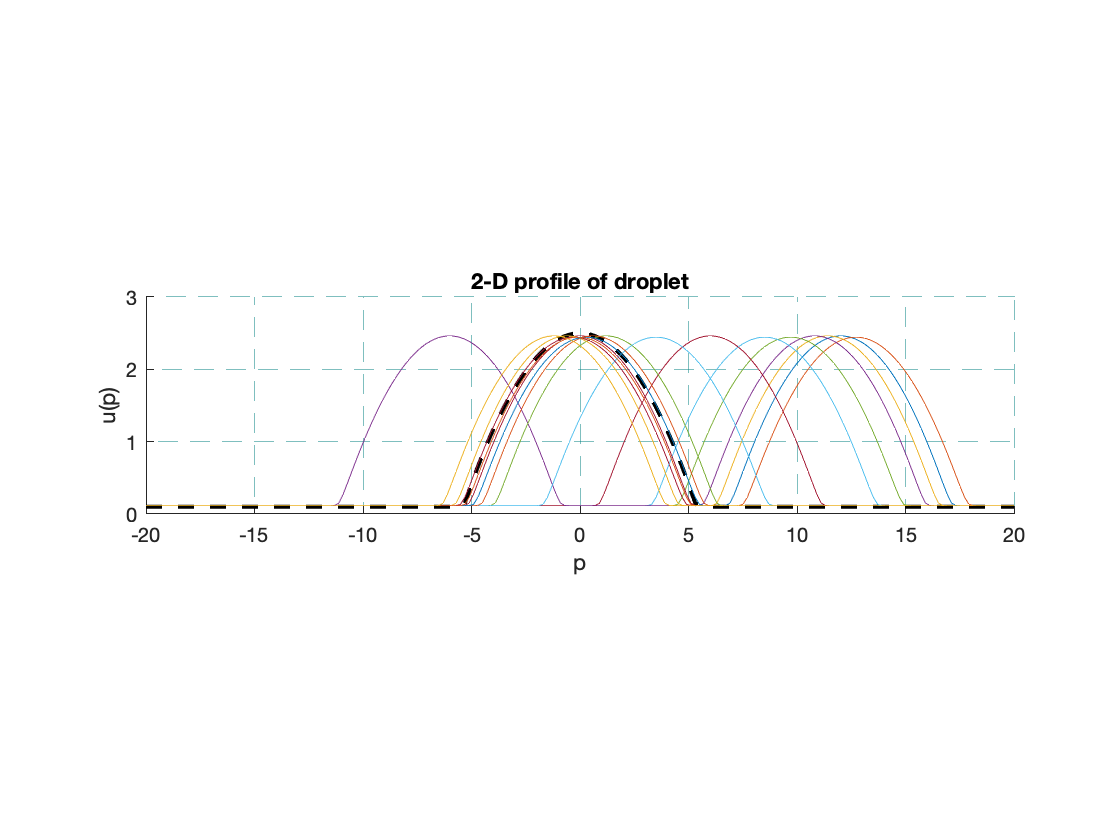


hold off


nC = size(historyC);
nC1 = nC(1);
dataHC = abs(historyC(1:8,1))';
dataHCi = abs(historyC(:,1))';
lineHC = 1:1:8;
lineHCi = 1:1:nC1;
[pC,SC,muC] = polyfit(lineHC,dataHC,1);
[pHC,deltaC] = polyval(pC,lineHC,SC,muC);

xCi = linspace(1, nC1, 100); 
yCi = interp1(lineHCi, dataHCi, xCi, 'spline', 'extrap');


Outside

figure;

hold on

plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

title('2-D profile of droplet');
% legend('Initial location','Optimised location','Target shape','Location','northwest');

[tSpanO,D1,D2,X,H0O,myObjective_Possition,conds_SolO,...
    fvalO,exitflagO,outputO,historyO,h_SolO,H_SolO,costO1,HO1]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xO0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           174.16         
     1            2           174.16         initial simplex
     2            4           174.16         reflect
     3            7           174.16         shrink
     4            9           174.16         contract outside
     5           12           174.16         shrink
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



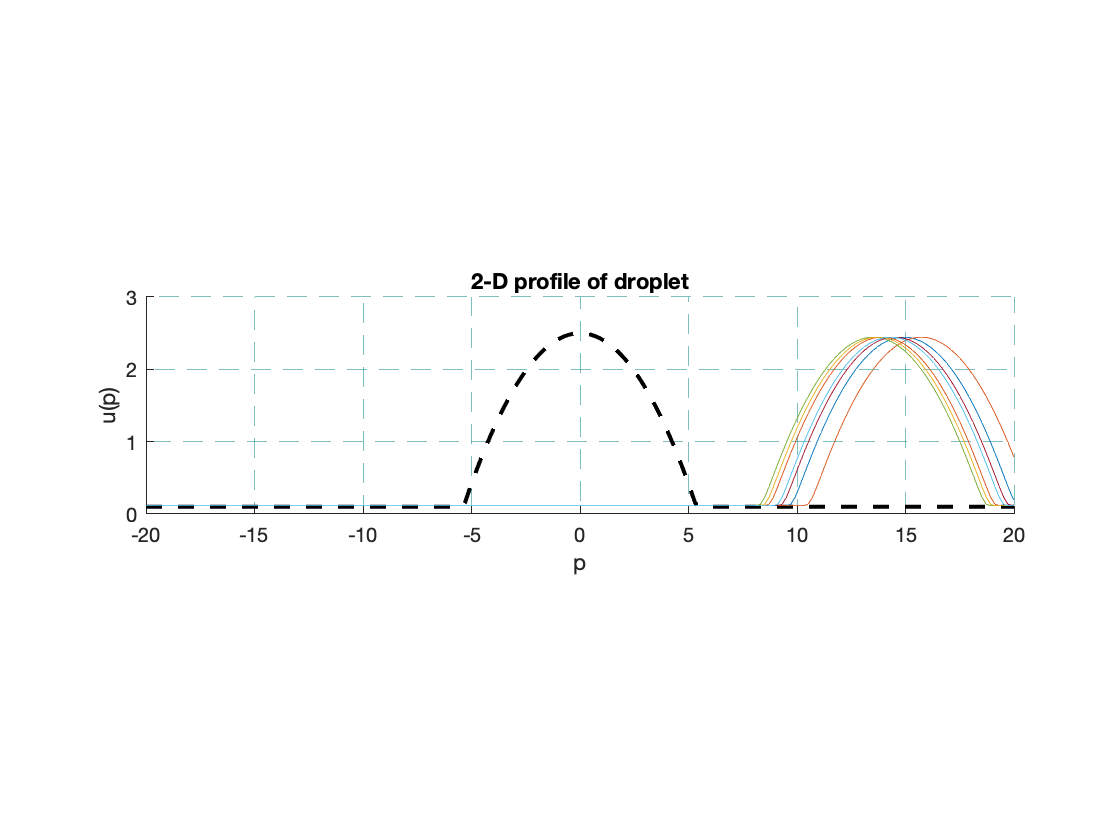


hold off


nO = size(historyO);
nO1 = nO(1);
dataHO = abs(historyO(1:nO1,1))';
dataHOi = abs(historyO(:,1))';
lineHO = 1:1:nO1;
lineHOi = 1:1:nO1;
[pO,SO,muO] = polyfit(lineHO,dataHO,1);
[pHO,deltaO] = polyval(pO,lineHO,SO,muO);

xOi = linspace(1, nO1, 100); 
yOi = interp1(lineHOi, dataHOi, xOi, 'spline', 'extrap');


**Inside Figures**

Fig. 1

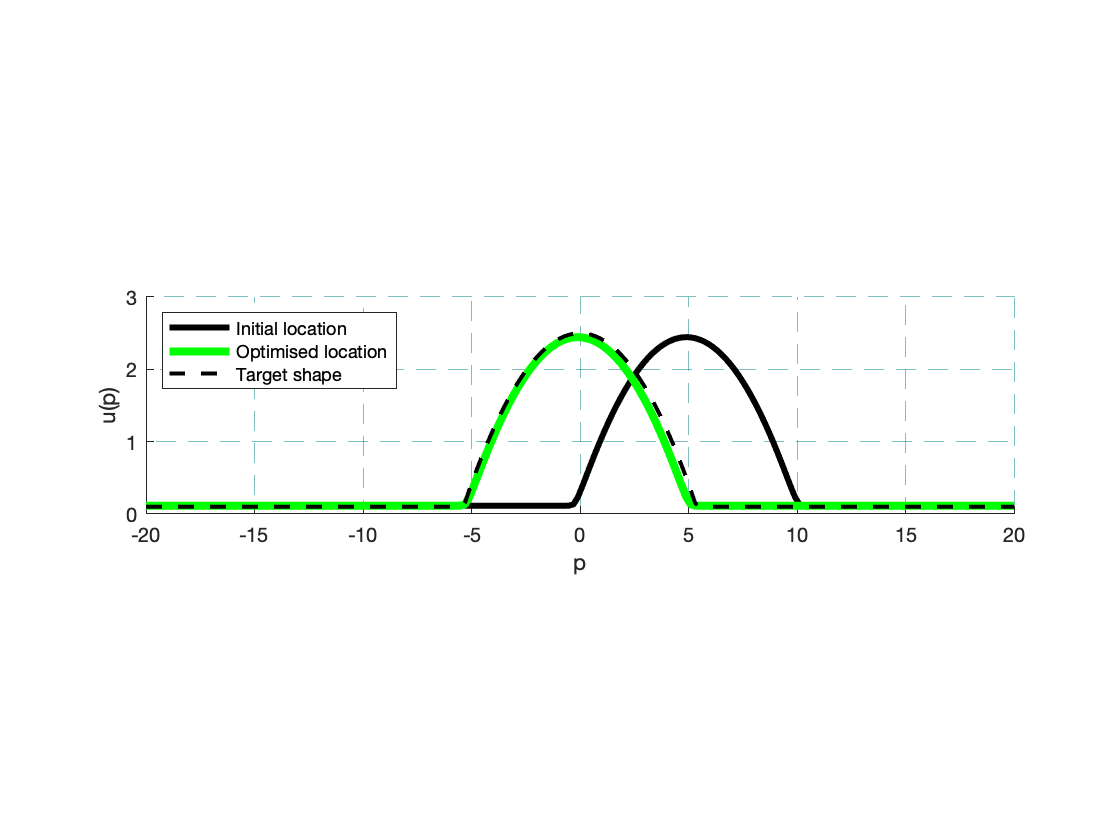

figure;
hold on


plot(X,H0I,'k-','linewidth',3);
% plot(X,HI1,'k:','linewidth',4);
plot(X,H_SolI,'g-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

% title('2-D profile of droplet');
legend('Initial location','Optimised location','Target shape','Location','northwest');
hold off

Fig. 2

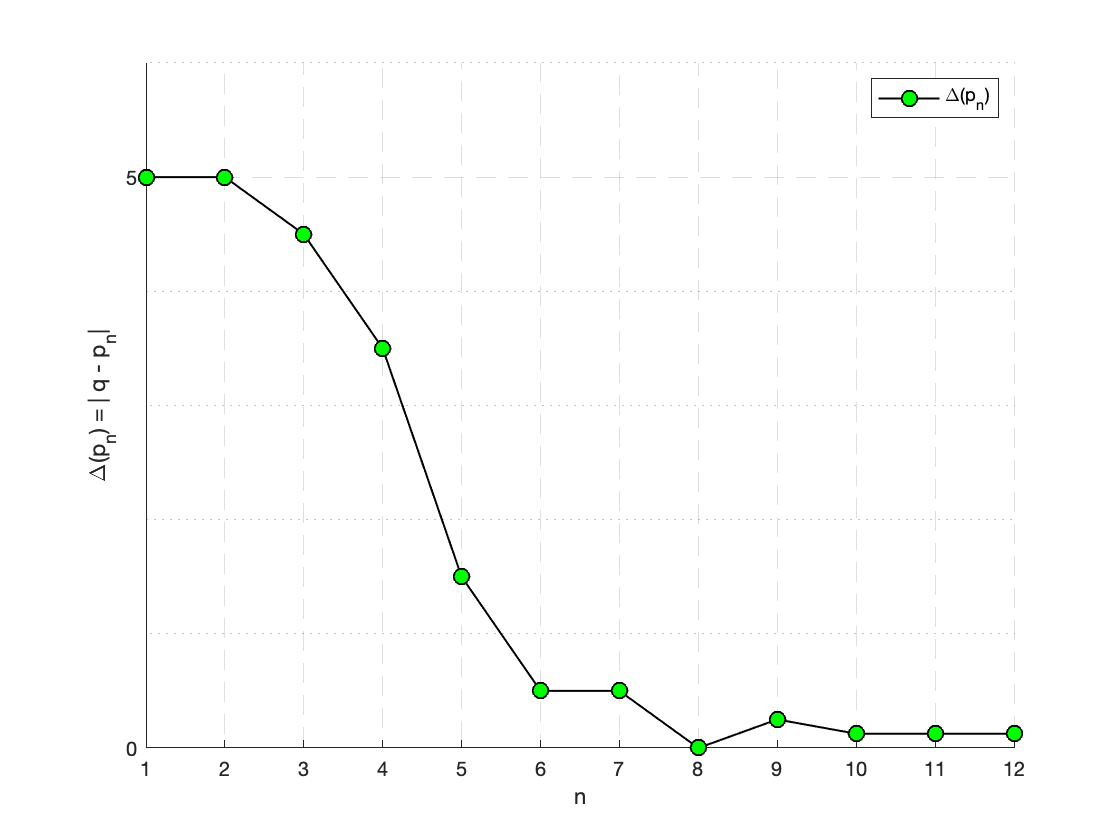

figure;
hold on

plot(lineHIi,dataHIi,'k-o',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);

% title('Iterative evolution of droplet distance to optimal location');
ylabel('\Delta(p_n) = | q - p_n|');
xlabel('n');
legend('\Delta(p_n)');

set(gca,'xtick',1:1:13);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 nI1]);
ylim([0 xI0+1]);
box off

hold off

Fig.3

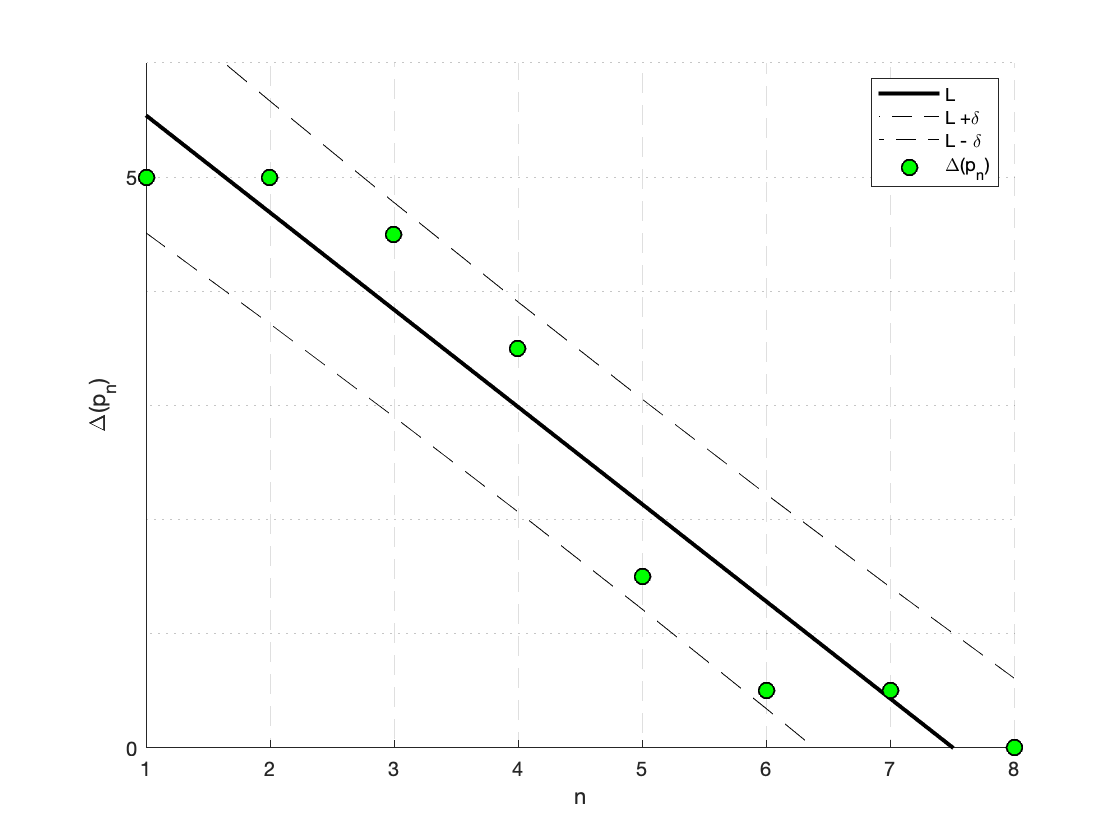

figure;
hold on

plot(lineHI,pHI,'-',...
    'Color','k',...
    'LineWidth',2);
plot(lineHI,pHI-1.4*deltaI,'k--');
plot(lineHI,pHI+1.4*deltaI,'k--');
plot(lineHI,dataHI,'ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);

% title('Line of best fit (L) in early iterations');
ylabel('\Delta(p_n)');
xlabel('n');
legend('L','L +\delta','L - \delta','\Delta(p_n)');

set(gca,'xtick',1:1:13);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 8]);
ylim([0 xI0+1]);

hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**Boarder Figures**

Fig. 1

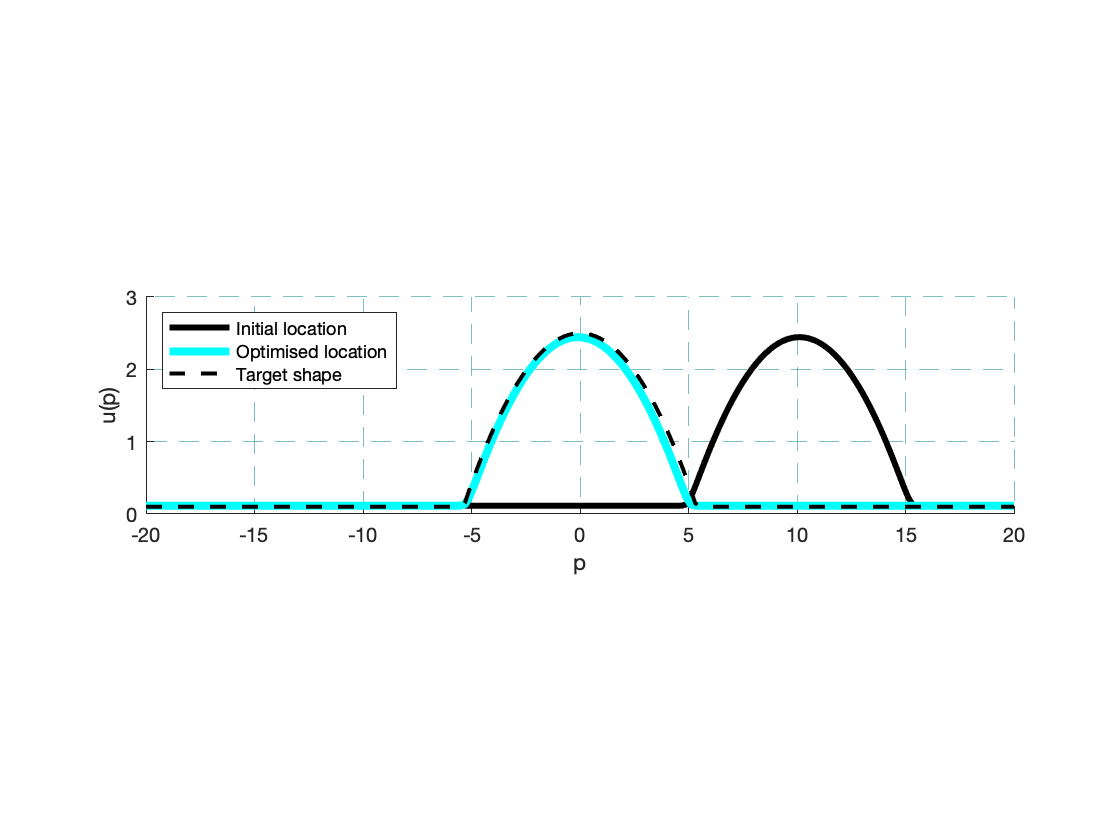

figure;
hold on

plot(X,H0B,'k-','linewidth',3);
% plot(X,HI1,'k:','linewidth',4);
plot(X,H_SolB,'c-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

% title('2-D profile of droplet');
legend('Initial location','Optimised location','Target shape','Location','northwest');
hold off

Fig. 2

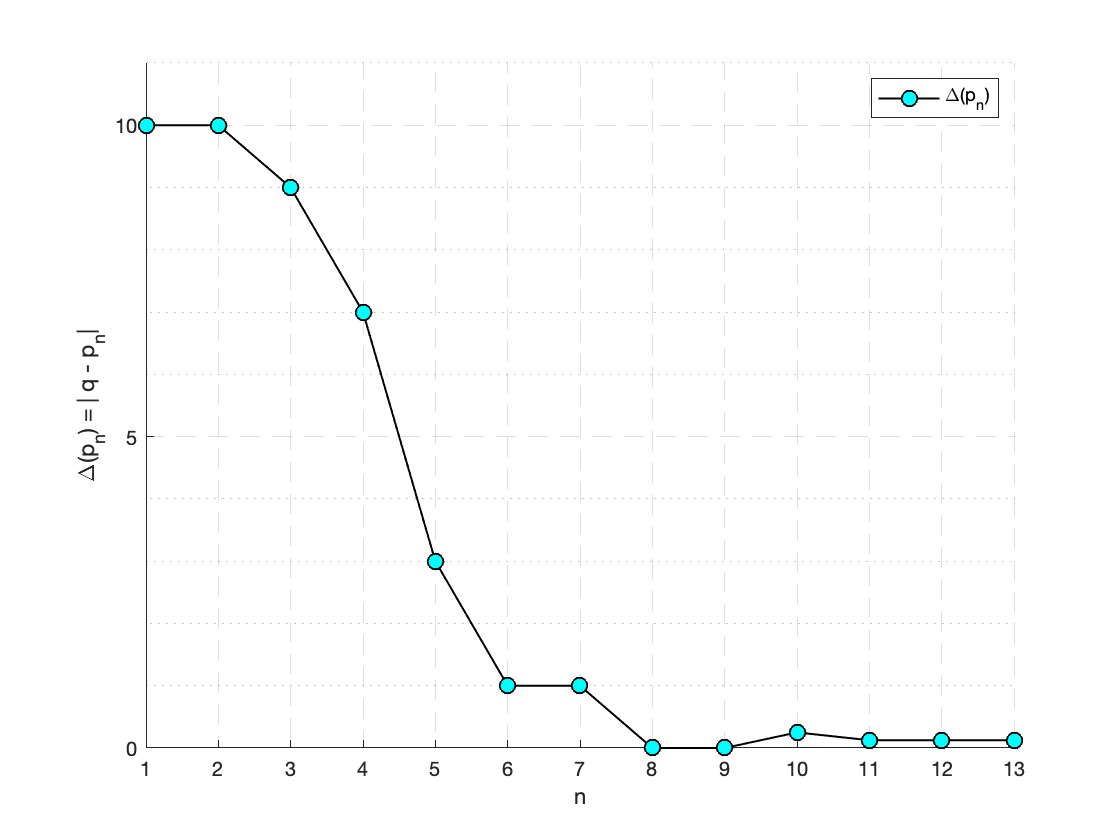

figure;
hold on

plot(lineHBi,dataHBi,'k-o',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);

% title('Iterative evolution of droplet distance to optimal location');
ylabel('\Delta(p_n) = | q - p_n|');
xlabel('n');
legend('\Delta(p_n)');

set(gca,'xtick',1:1:21);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 nB1]);
ylim([0 xB0+1]);
box off

hold off

Fig.3

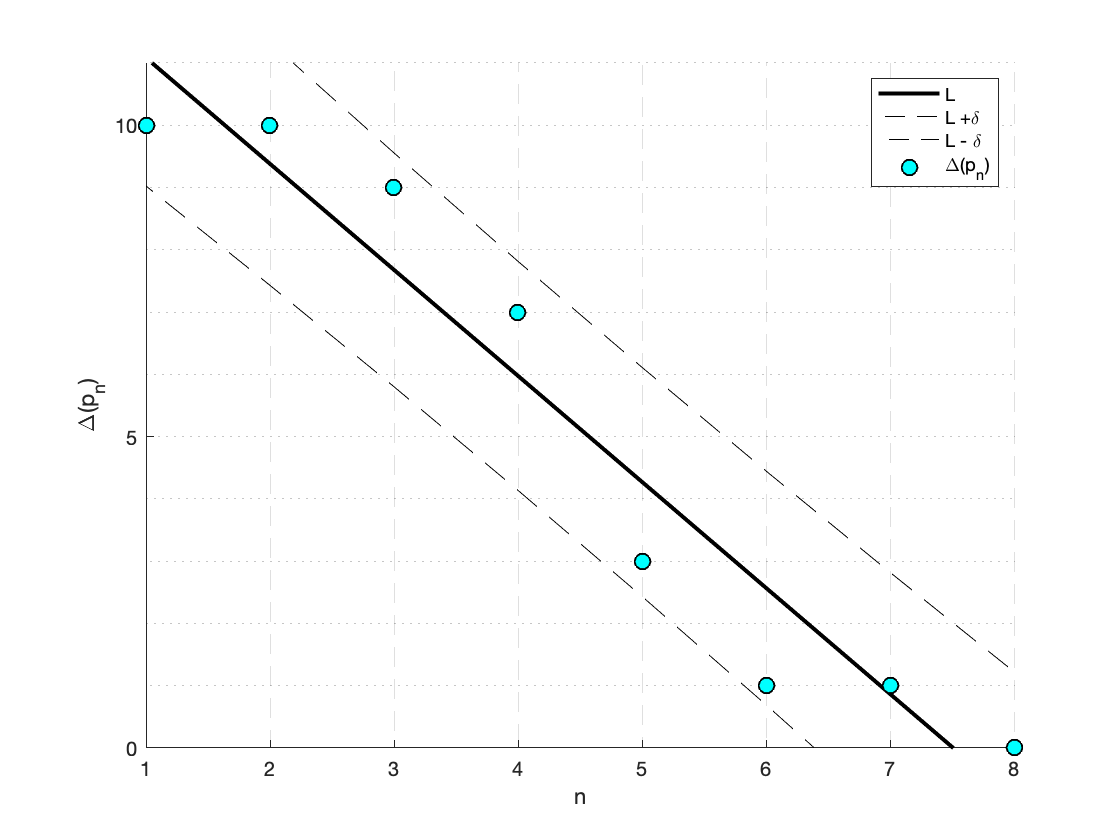

figure;
hold on

plot(lineHB,pHB,'-',...
    'Color','k',...
    'LineWidth',2);
plot(lineHB,pHB-1.4*deltaB,'k--');
plot(lineHB,pHB+1.4*deltaB,'k--');
plot(lineHB,dataHB,'ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);

% title('Line of best fit (L) in early iterations');
ylabel('\Delta(p_n)');
xlabel('n');
legend('L','L +\delta','L - \delta','\Delta(p_n)');

set(gca,'xtick',1:1:13);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 8]);
ylim([0 xB0+1]);

hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**2nd - Boarder Figures**

Fig. 1

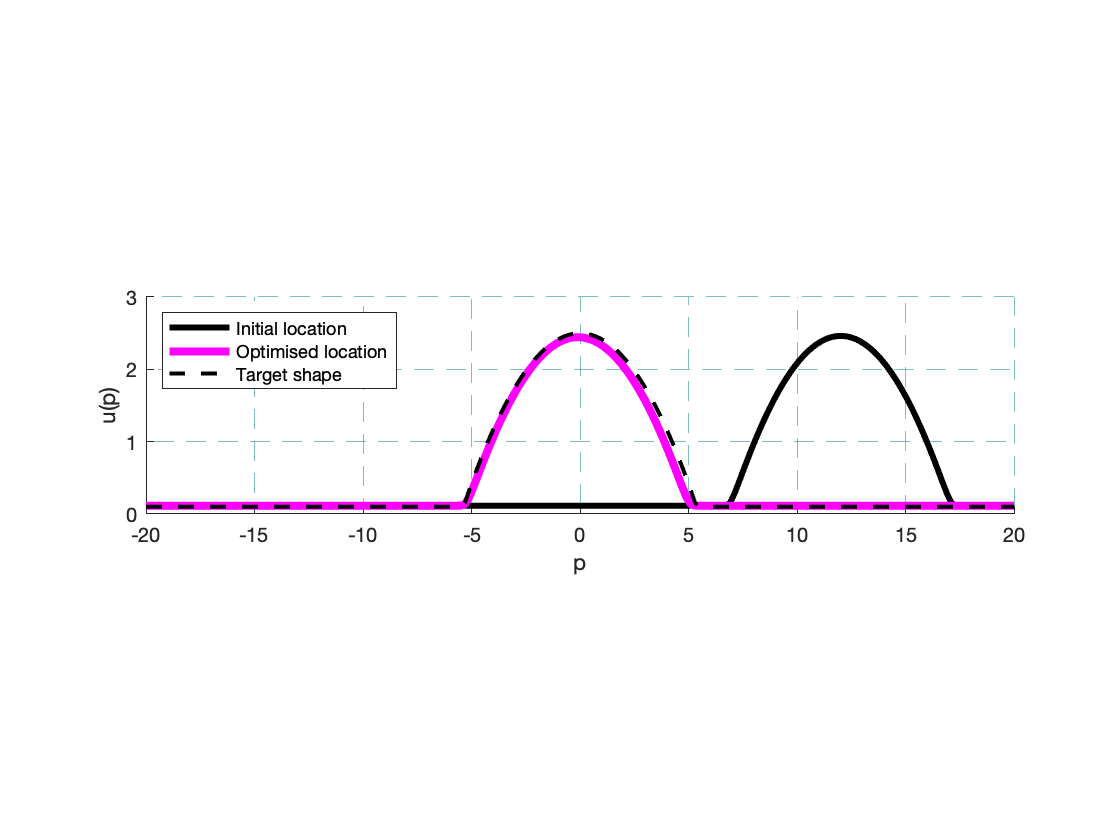

figure;
hold on

plot(X,H0C,'k-','linewidth',3);
% plot(X,HI1,'k:','linewidth',4);
plot(X,H_SolC,'m-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

% title('2-D profile of droplet');
legend('Initial location','Optimised location','Target shape','Location','northwest');
hold off

Fig. 2

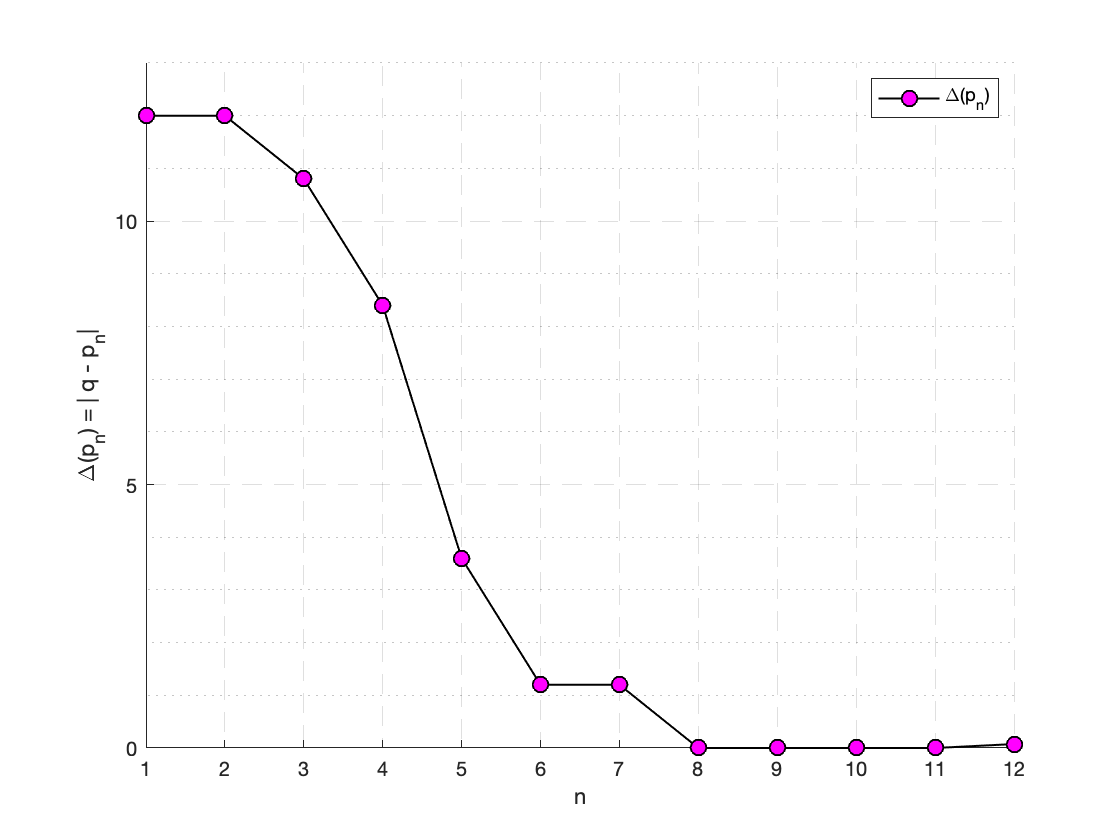

figure;
hold on

plot(lineHCi,dataHCi,'k-o',...
    'MarkerSize',8,...
    'MarkerFaceColor','m',...
    'LineWidth',1);

% title('Iterative evolution of droplet distance to optimal location');
ylabel('\Delta(p_n) = | q - p_n|');
xlabel('n');
legend('\Delta(p_n)');

set(gca,'xtick',1:1:21);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 nC1]);
ylim([0 xC0+1]);
box off

hold off

Fig.3

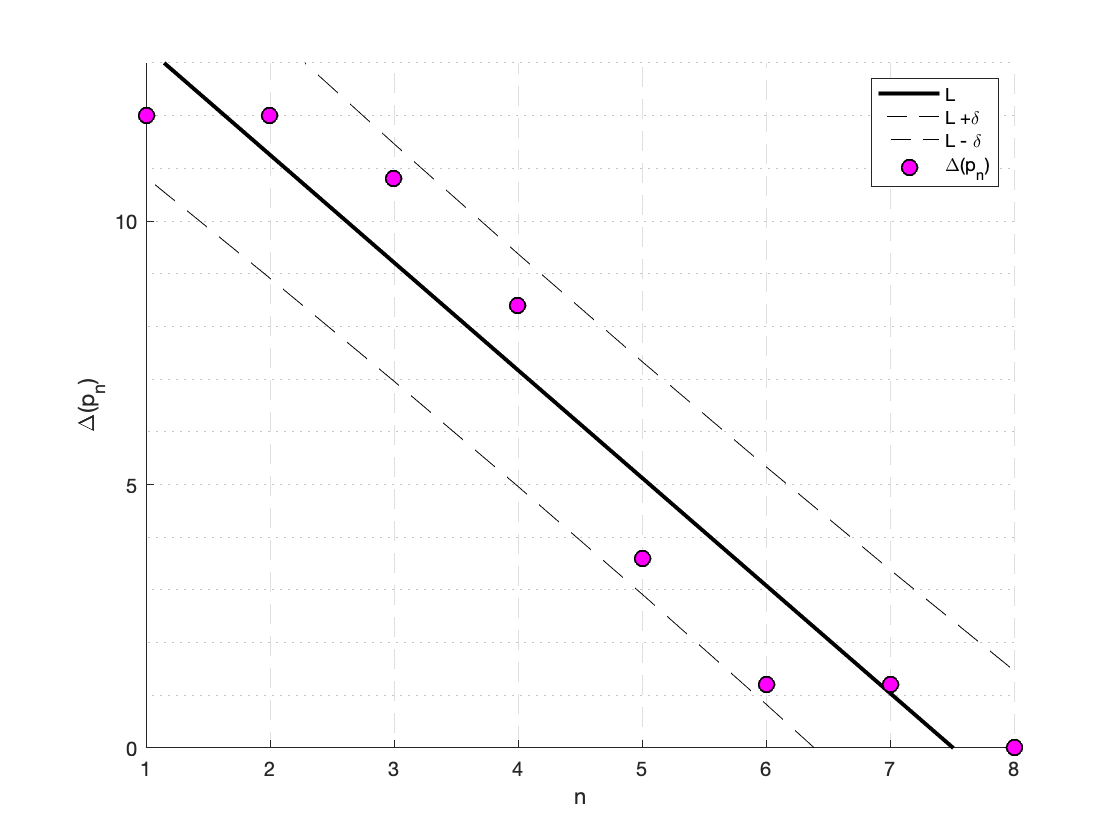

figure;
hold on

plot(lineHB,pHC,'-',...
    'Color','k',...
    'LineWidth',2);
plot(lineHC,pHC-1.4*deltaC,'k--');
plot(lineHC,pHC+1.4*deltaC,'k--');
plot(lineHC,dataHC,'ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','m',...
    'LineWidth',1);

% title('Line of best fit (L) in early iterations');
ylabel('\Delta(p_n)');
xlabel('n');
legend('L','L +\delta','L - \delta','\Delta(p_n)');

set(gca,'xtick',1:1:13);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 8]);
ylim([0 xC0+1]);

hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**Outside Figures**

Fig. 1

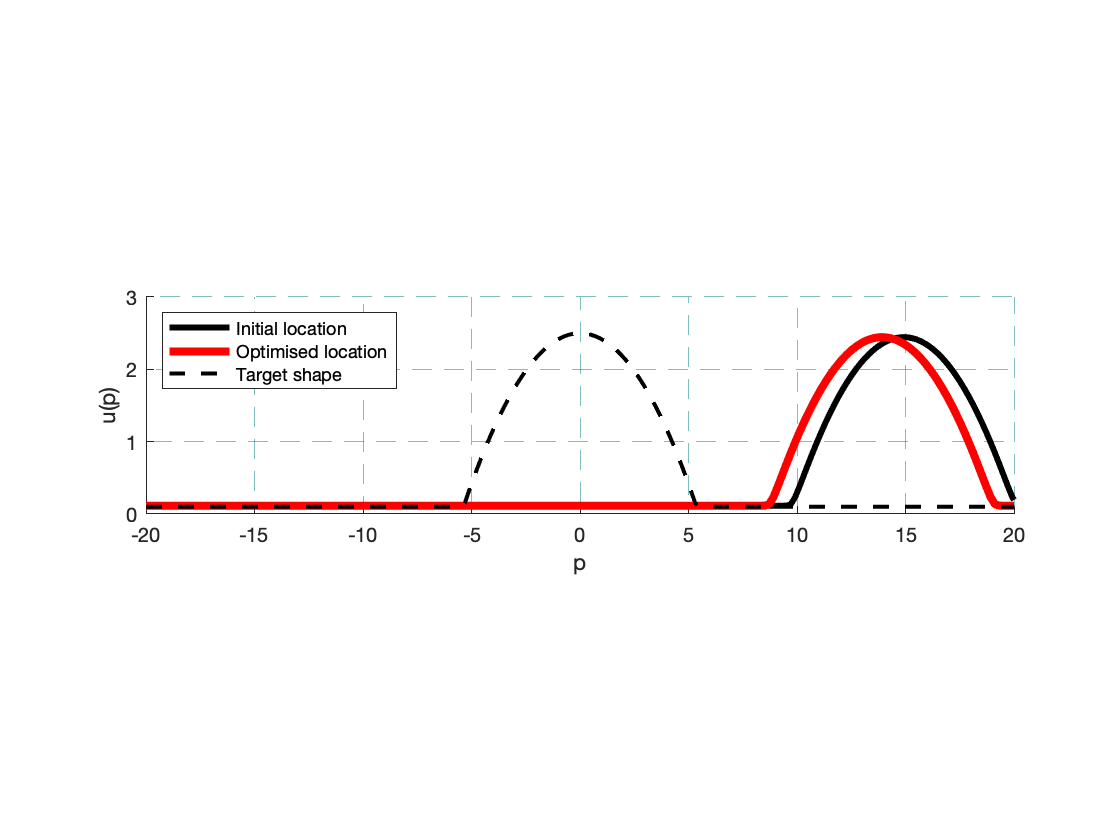

figure;
hold on

plot(X,H0O,'k-','linewidth',3);
plot(X,H_SolO,'r-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);

xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u(p)');

grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

% title('2-D profile of droplet');
legend('Initial location','Optimised location','Target shape','Location','northwest');
hold off

Fig. 2

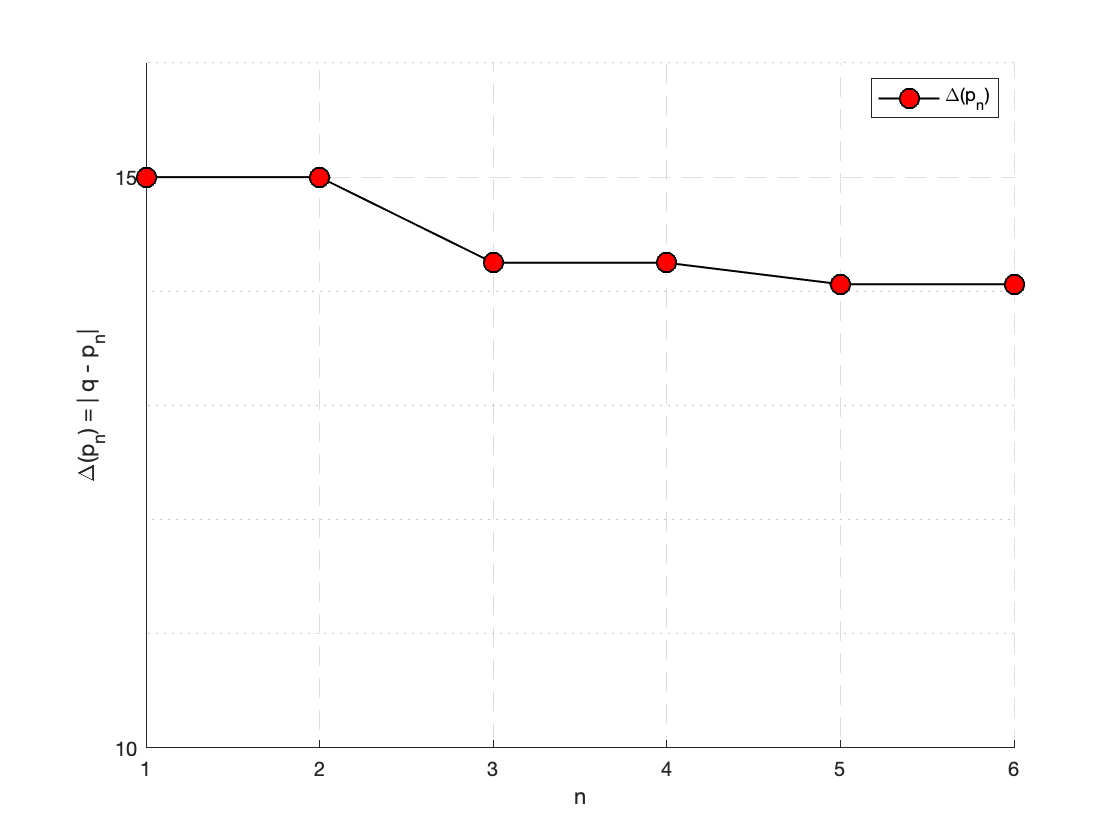

figure;
hold on

plot(lineHOi,dataHOi,'-ko',...
    'MarkerSize',10,...
    'MarkerFaceColor','r',...
    'LineWidth',1);

% title('Iterative evolution of droplet distance to optimal location');
ylabel('\Delta(p_n) = | q - p_n|');
xlabel('n');
legend('\Delta(p_n)');

set(gca,'xtick',1:1:21);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 nO1]);
ylim([10 xO0+1]);
box off

hold off

Fig.3

% figure;
% hold on
% 
% plot(lineHO,pHO,'-',...
%     'Color','k',...
%     'LineWidth',2);
% plot(lineHO,pHO-1.4*deltaO,'k--');
% plot(lineHO,pHO+1.4*deltaO,'k--');
% plot(lineHO,dataHO,'o',...
%     'MarkerSize',8,...
%     'MarkerFaceColor','r',...
%     'LineWidth',1);
% 
% % title('Line of best fit (L) in early iterations');
% ylabel('\Delta(p_n) = | q - p_n|');
% xlabel('n');
% legend('L','L +\delta','L - \delta','\Delta(p_n)');
% 
% set(gca,'xtick',1:1:13);
% set(gca,'ytick',0:5:100);
% 
% ax = gca;
% ax.GridLineStyle = '--';
% ax.XGrid = 'on';
% ax.YGrid = 'off';
% ax.MinorGridLineStyle =':';
% ax.XMinorGrid = 'off';
% ax.YMinorGrid = 'on';
% 
% xlim([1 9]);
% ylim([10 xO0+1]);
% 
% hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**Joint Figures**

Joint Figure

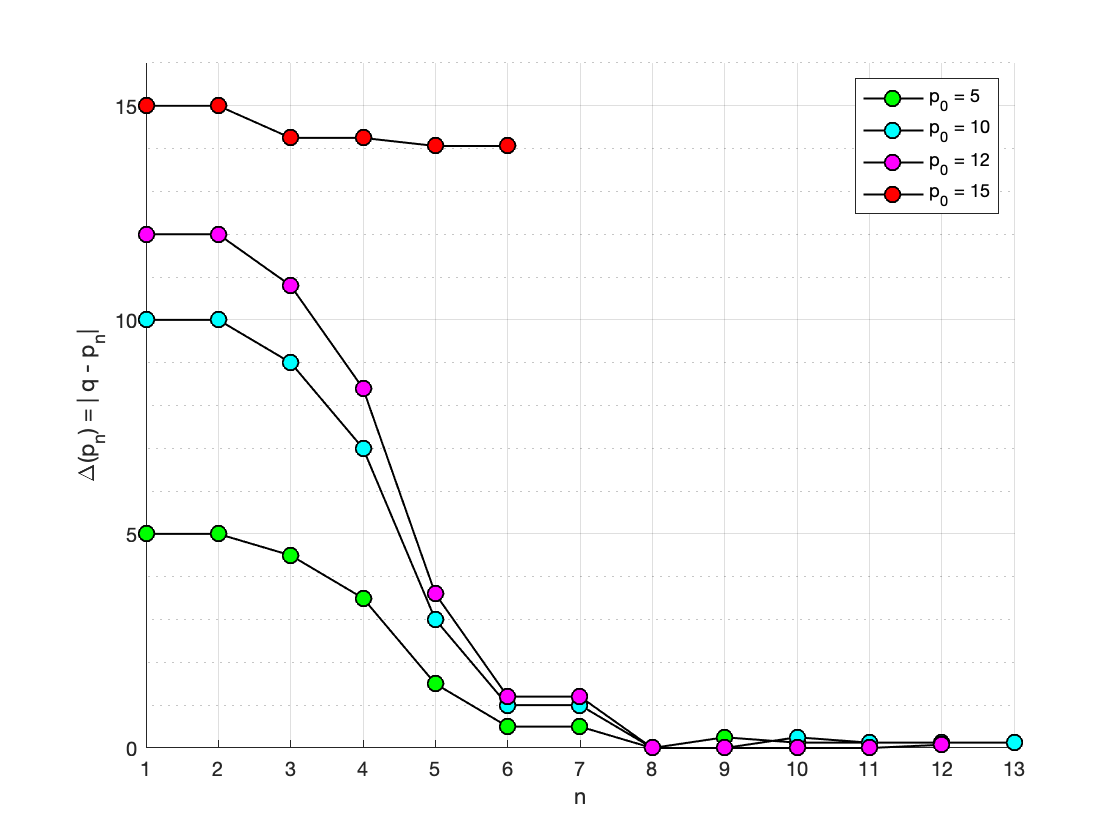

figure;
hold on

plot(lineHIi,dataHIi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(lineHBi,dataHBi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
plot(lineHCi,dataHCi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','m',...
    'LineWidth',1);
plot(lineHOi,dataHOi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','r',...
    'LineWidth',1);

% title('Iterative evolution of droplet distance to optimal location');
ylabel('\Delta(p_n) = | q - p_n|');
xlabel('n');
legend('p_0 = 5','p_0 = 10','p_0 = 12','p_0 = 15');

set(gca,'xtick',1:1:21);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 nB1]);
ylim([0 xO0+1]);
box off

hold off

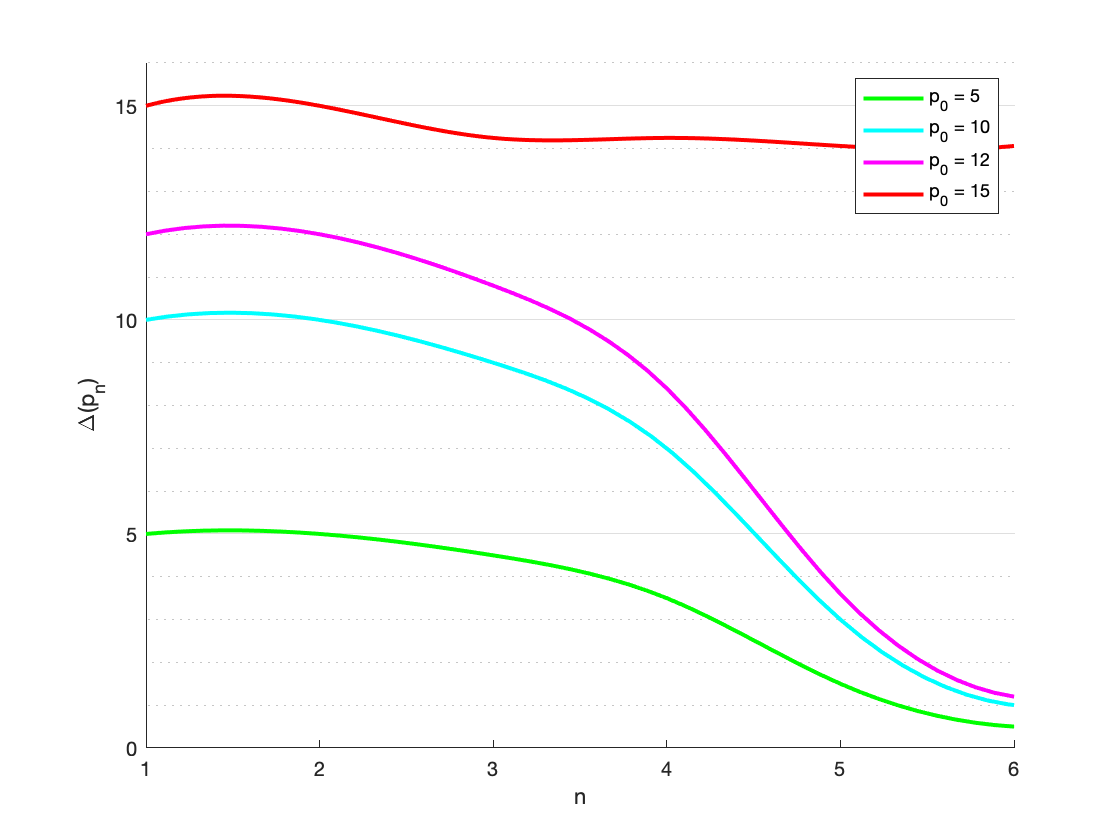


figure;
hold on

plot(xIi,yIi,'-g',...
    'MarkerSize',10,...
    'LineWidth',2);
plot(xBi,yBi,'-c',...
    'MarkerSize',10,...
    'LineWidth',2);
plot(xCi,yCi,'-m',...
    'MarkerSize',10,...
    'LineWidth',2);
plot(xOi,yOi,'-r',...
    'MarkerSize',10,...
    'LineWidth',2);

% title('Iterative evolution of droplet distance to optimal location');
ylabel('\Delta(p_n)');
xlabel('n');
legend('p_0 = 5','p_0 = 10','p_0 = 12','p_0 = 15');

set(gca,'xtick',1:1:21);
set(gca,'ytick',0:5:100);

ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';

xlim([1 6]);
ylim([0 xO0+1]);
box off

hold off